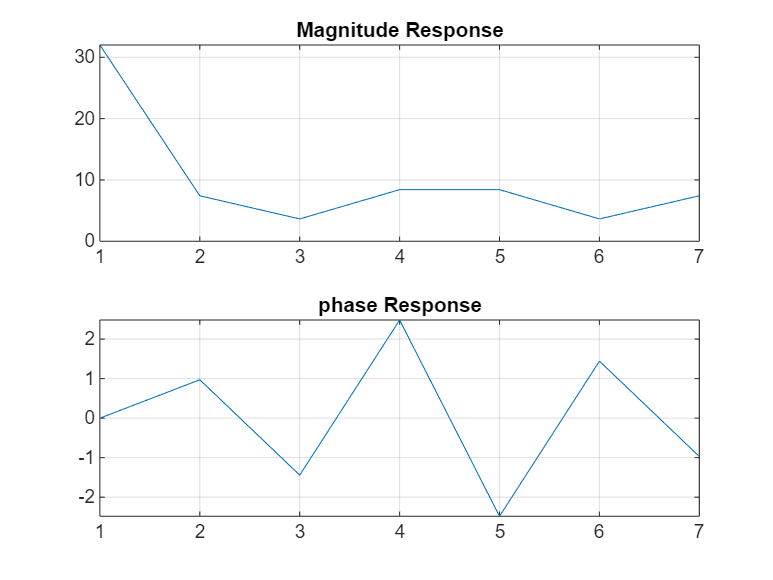

%USING INBUILT FUNCTION
n = 0:6;
x = [4 6 2 1 7 4 8]; % function is given
a = fft(x);
mag = abs(a);
pha = angle(a);
subplot(2,1,1);
plot(mag);
grid on
title('Magnitude Response');
subplot(2,1,2);
plot(pha);
grid on
title('phase Response');

%N-POINT FFT WITHOUT USING INBUILT FUNCTION OF USER DEFINED FUNCTION
x=input('Enter the sequence x[n]= ');
N=input('Enter the value N point= ');
L=length(x);
x_n=[x,zeros(1,N-L)];
for i=1:N
for j=1:N
temp=-2*pi*(i-1)*(j-1)/N;
DFT_mat(i,j)=exp(complex(0,temp));
end
1
end
X_k=DFT_mat*x_n';
disp('N point DFT is X[k] = ');
disp(X_k);
mag=abs(X_k);
phase=angle(X_k)*180/pi;
subplot(2,1,1);
stem(mag);
xlabel('frequency index k');
ylabel('Magnitude of X[k]');
axis([0 N+1 -2 max(mag)+2]);
subplot(2,1,2);
stem(phase);
xlabel('frequency index k');
ylabel('Phase of X[k]');
axis([0 N+1 -180 180]);

%For user defined sequence :
x=input('Enter the sequence :-');
n=input('Enter the length of fft :-'); %compute fft
disp('fourier transformed signal');
X=fft(x,n);
subplot(1,2,1);stem(x);
title('Input signal');
xlabel('n --->');
ylabel('x(n) -->');grid;
subplot(1,2,2);stem(X);
title('fft of input x(n) is:');
xlabel('Real axis --->');
ylabel('Imaginary axis -->');
grid;

%For user defined sequence :
x=input('Enter the sequence :-');
n=input('Enter the length of fft :-'); %compute fft
disp('Fourier transformed signal');
X=fft(x,n)
subplot(1,2,1);
stem(x);
title('Input signal');
xlabel('n --->');
ylabel('x(n) -->');
grid;
subplot(1,2,2);stem(X);
title('FFT of input x(n) is:');
xlabel('Real axis --->');
ylabel('Imaginary axis -->');
grid;

%For user defined sequence :
x=input('Enter the sequence :-');
n=input('Enter the length of fft :-'); %compute fft
disp('Fourier transformed signal');
X=fft(x,n)
subplot(1,2,1);
stem(x);
title('Input signal');
xlabel('n --->');
ylabel('x(n) -->');
grid;
subplot(1,2,2);
stem(X);
title('FFT of Input x(n) is:');
xlabel('Real axis --->');
ylabel('Imaginary axis -->');
5
grid;